% filename='portIV_freqResp_50ohm_realGeoNoBearings_wZ.txt';

## Name of file

clf;
filename='portIVkimballMirror_R50.txt';

## Ben's Code

data=readtable(filename,'HeaderLines',5);
data=table2array(data);

freq=data(:,1);
freqSteps=diff(freq);
realV=data(:,2);
imagV=data(:,3)*1i;
realI=data(:,4);
imagI=data(:,5)*1i;
V=realV+imagV;
I=realI+imagI;
z=V./I;
%z=data(:,6);%V./I;
realZ=real(z);
imagZ=imag(z);
Zabs=abs(z);
ZPhase=unwrap(angle(z));

## John's Code

Default range assumed from 10MHz up

if 0  % Extends the range if 1, else Ben's code if 0;
    johnIndex = 1;
%     freqStart = 1e3;
%     freqEnd = 5e6;
%     freqPoints = 2;
%     pre_freq = linspace(freqStart,freqEnd,freqPoints);
    pre_freq = 1e5;

    % freqDiff = freq(2)-freq(1);
    % zDiff = z(2)-z(1);
    capacitance = 1/(2*pi.*freq(johnIndex).*abs(z(johnIndex)))   % Z=1/jwC .. C=1/(j2pi*f*|Z|)
    % zSlope = zDiff/freqDiff;
    pre_z = (i*2*pi*capacitance*pre_freq).^(-1);
    pre_freqT = pre_freq.';
    
    freq = [pre_freqT; freq];
    pre_zT = pre_z.';
    z = [pre_zT; z];
    
    realZ=real(z);
    imagZ=imag(z);
    Zabs=abs(z);
    ZPhase=unwrap(angle(z));
end

## Ben's Code

ratFit=rationalfit(freq,z);
sObject=sparameters(z,freq);
passiveRatFit=makepassive(ratFit,sObject);

generateSPICE(ratFit,'testNetworkJS.ckt');

fitResp = freqresp(ratFit,freq);
fitRespMag=abs(fitResp);
fitRespPhase=angle(fitResp);

passiveTest=ispassive(ratFit)

passiveTest = logical
   0


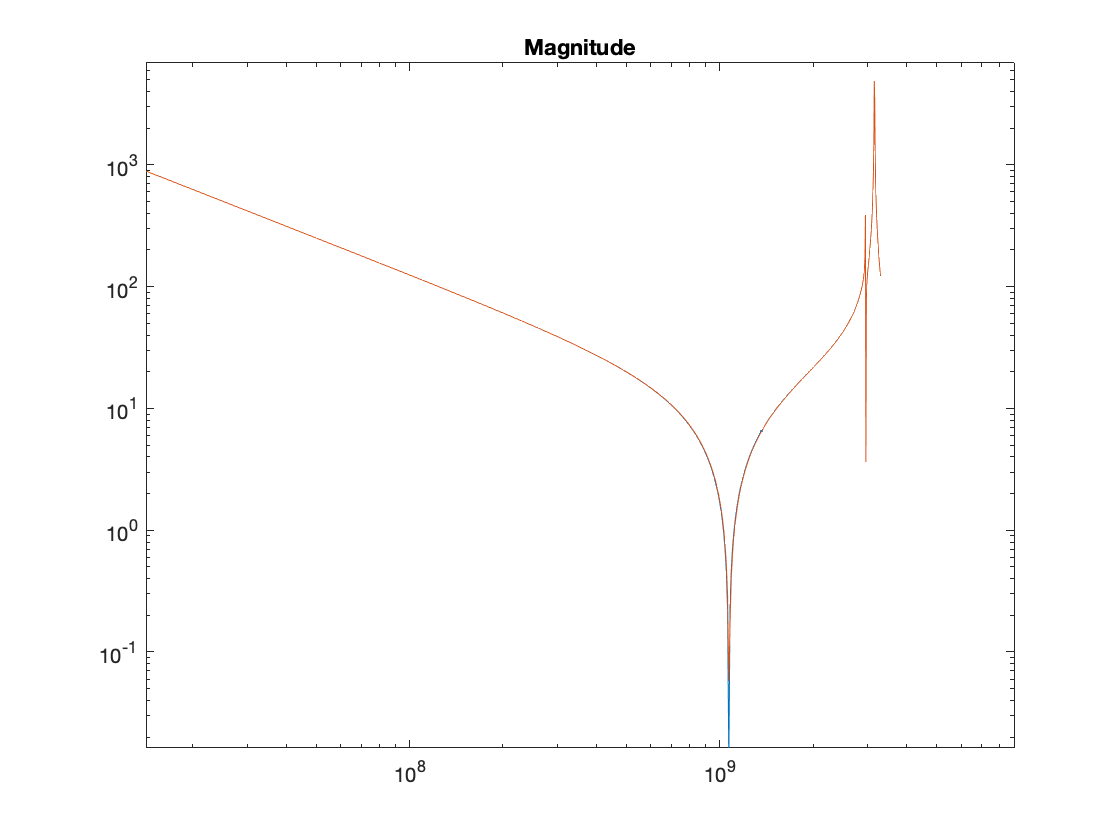


passiveResp = freqresp(passiveRatFit,freq);
passiveRespMag = abs(passiveResp);
passiveRespPhase = angle(passiveResp);

figure()
loglog(freq,Zabs);
hold on
loglog(freq,fitRespMag);
% loglog(freq,passiveRespMag);
hold on
title('Magnitude');

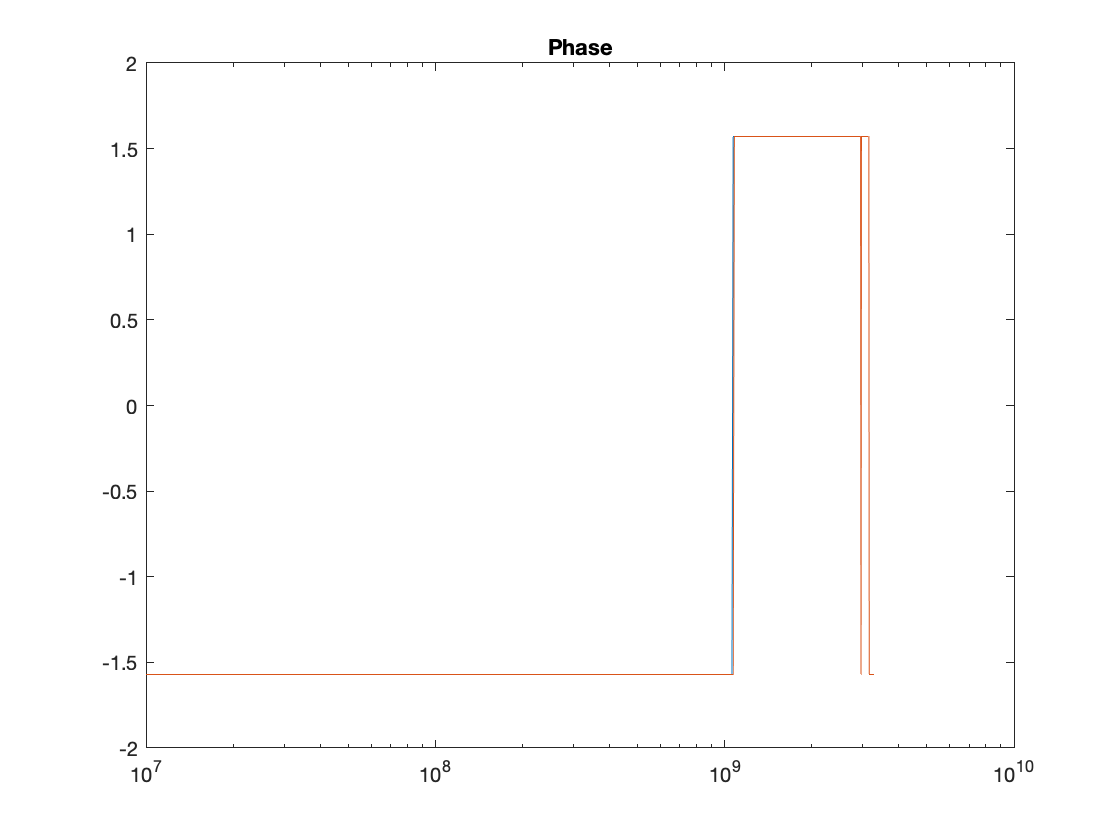


figure()
semilogx(freq,ZPhase);
hold on
semilogx(freq,fitRespPhase);
% semilogx(freq,passiveRespPhase);
title('Phase');

% %%
% data=frd(z,freq);
% TFsysTest=tfest(data,7);
% 
% zTF=tf(TFsysTest.Numerator,TFsysTest.Denominator);
% %bode(zTF);
% fitTFatFreq=freqresp(zTF,freq);
% fitTFatFreq=squeeze(fitTFatFreq);
% magFitZ=abs(fitTFatFreq);
% phaseFitZ=imag(fitTFatFreq);
% 
% figure()
% title('Magnitude')
% semilogx(freq,Zabs)
% hold on
% yyaxis right
% semilogx(freq,magFitZ);
% 
% figure()
% title('phase')
% semilogx(freq,ZPhase)
% hold on
% yyaxis right
% semilogx(freq,phaseFitZ);